# Lattice characterization

expt_bag_path = "lattice_calibration_data/15x15x15/trial1/lattice_data_2";
bag = ros2bagreader(expt_bag_path); 
bag_info = ros2("bag","info",expt_bag_path);

filtered data

ft_bag = select(bag,"Topic",{"/nano_17_proxy/ft"});
ft_data = readMessages(ft_bag);

% make t vector, fz vector, z vector, z' vector
dim = size(ft_data);
n = dim(1,1);

t = [];
fz = [];
z = [];

for i = 1:n
    time_stamp = ft_data{i}.data(1);
    is_available = canTransform(bag,"left_tool0","world",time_stamp);
    if is_available
        current_transform = getTransform(bag,"left_tool0","world",time_stamp);
        t(i) = time_stamp;
        fz(i) = ft_data{i}.data(4);
        z(i) = -current_transform.transform.translation.z;
    end
end

t = t';
fz = fz';
z = z';

z = z-z(1,1);
t_adjusted = t-t(1,1);


front_crop_seconds = 5;
back_crop_seconds = 5;

mean_sampling_time = mean(diff(t_adjusted));

front_window = int16(front_crop_seconds/mean_sampling_time);
back_window = int16(back_crop_seconds/mean_sampling_time);

% crop the starting as well till 10s
t_adjusted(1:front_window) = [];
fz(1:front_window) = [];
z(1:front_window) = [];

% crop the starting as well till 10s
t_adjusted(end-back_window:end) = [];
fz(end-back_window:end) = [];
z(end-back_window:end) = [];

length = size(t_adjusted);
length = length(1,1);

delta_z = zeros(length,1,"double");
delta_z(1) = 0;
delta_z(length) = 0;
z_v = zeros(length,1,"double");
z_v(1) = 0;
z_v(length) = 0;

for i=2:length-1
    delta_z(i) = (z(i+1) - z(i-1))/2;
    z_v(i) = delta_z(i)/(t_adjusted(i+1) - t_adjusted(i-1));

end

z_v_filtered = lowpass(z_v,10,1e3);

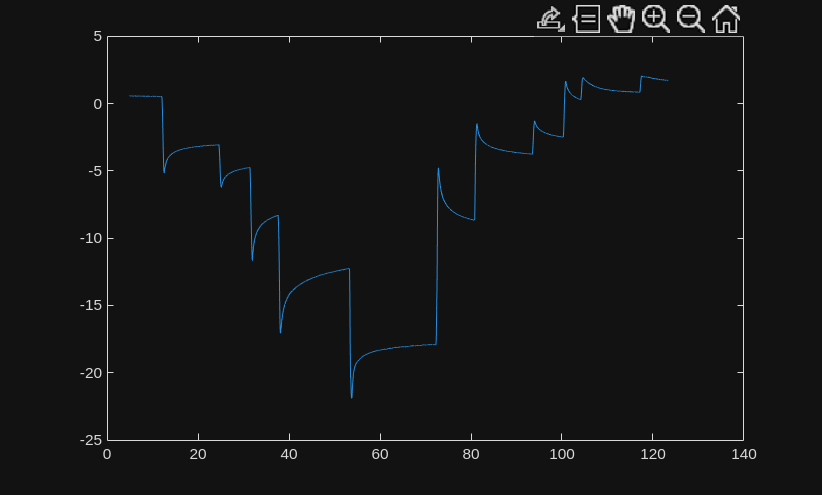

% now we have t,fz,z,z_vits = size(t_adjusted,1);
% plot everything 
plot(t_adjusted,fz);

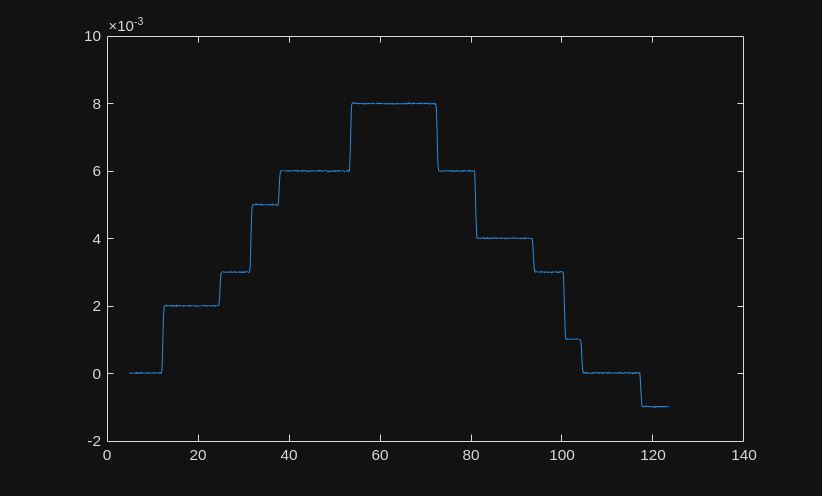

plot(t_adjusted,z);

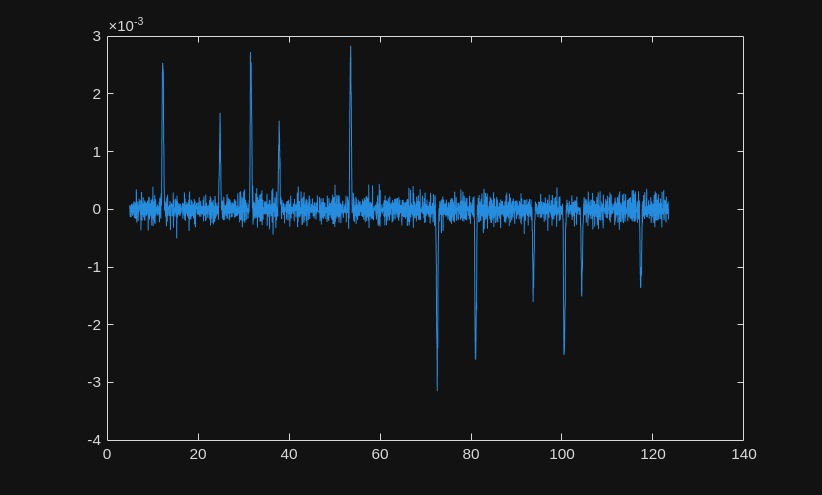

plot(t_adjusted,z_v);

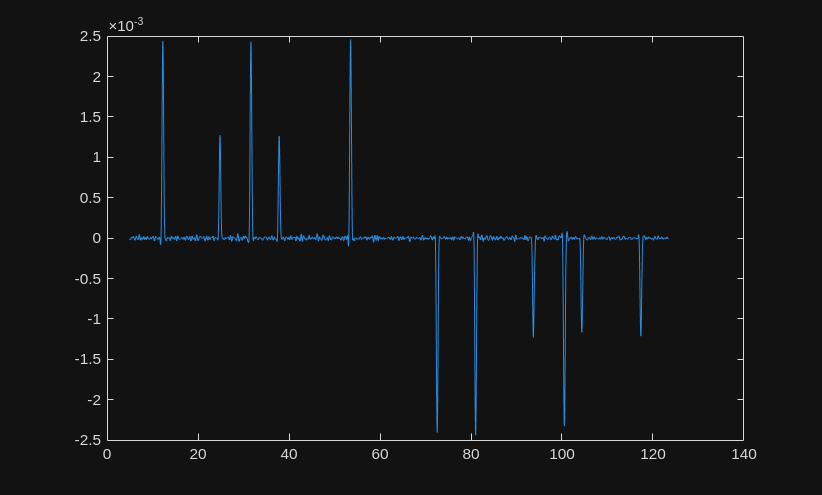

plot(t_adjusted,z_v_filtered);

% now linear regression
A = [z z_v_filtered];
projected_coeffs = - inv(A' * A) * A' * fz;
k = projected_coeffs(1,1);
zeta = projected_coeffs(2,1);

k,zeta

k = 1.9468e+03

zeta = 1.5947e+03

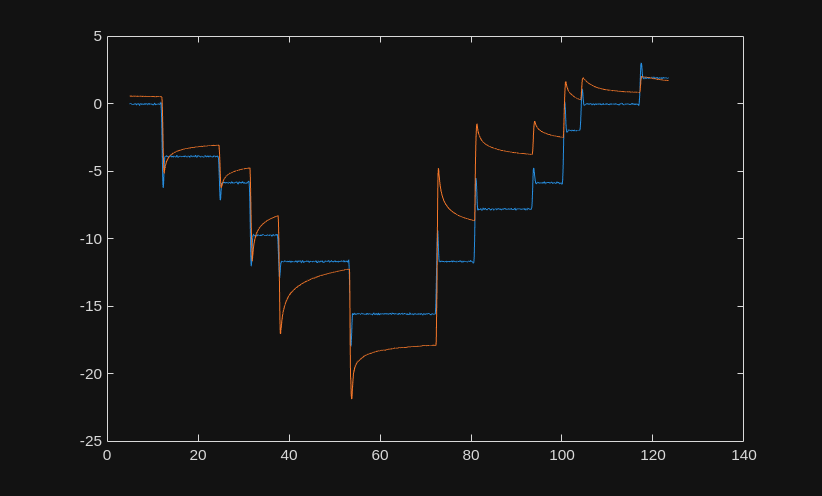

% Calculate the fitted force based on
%  the linear regression coefficients
fz_fitted = -A * projected_coeffs;
plot(t_adjusted,fz_fitted);

hold on
plot(t_adjusted,fz);
hold off

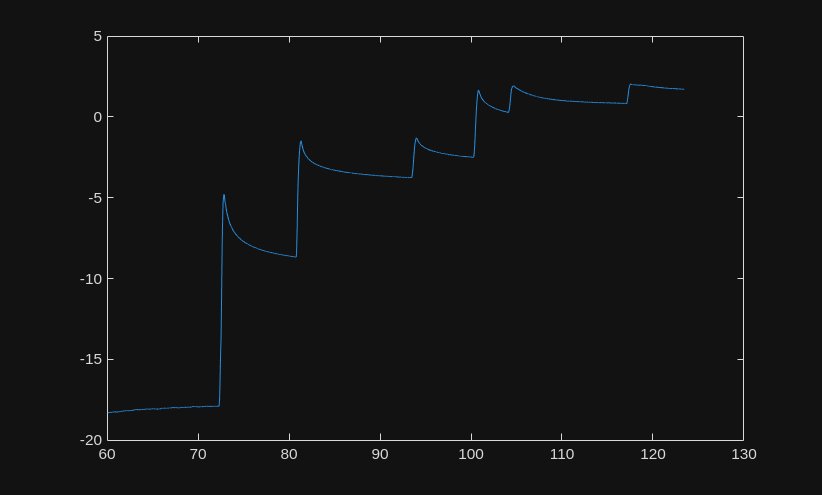

% now with relaxation component
% linear regression

% first select the first half
for i=1:length
    if t_adjusted(i) > 60
        break
    end
end


z_compression = z;
z_v_filtered_compression = z_v_filtered;
t_adjusted_compression = t_adjusted;
fz_compression = fz;
z_decompression = z;
z_v_filtered_decompression = z_v_filtered;
t_adjusted_decompression = t_adjusted;
fz_decompression = fz;

z_compression(i:end) = [];
z_v_filtered_compression(i:end) = [];
t_adjusted_compression(i:end) = [];
fz_compression(i:end) = [];

z_decompression(1:i) = [];
z_v_filtered_decompression(1:i) = [];
t_adjusted_decompression(1:i) = [];
fz_decompression(1:i) = [];

plot(t_adjusted_decompression,fz_decompression);

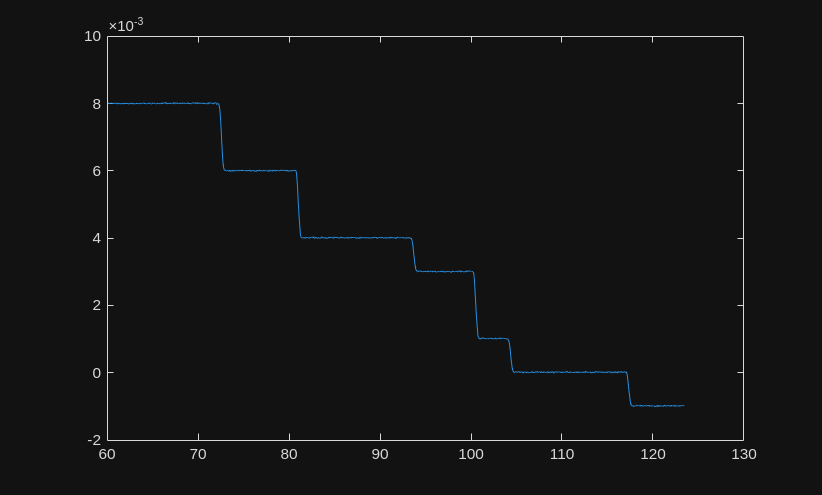

plot(t_adjusted_decompression,z_decompression);

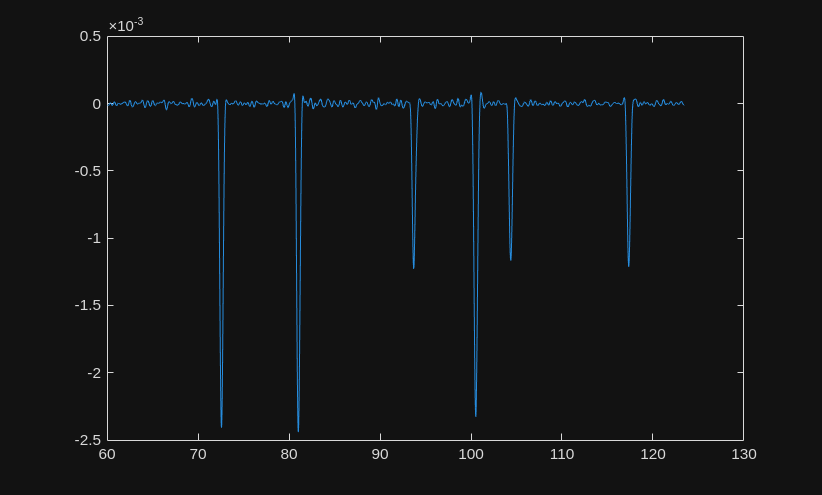

%plot(t_adjusted,z_v_decompression);
plot(t_adjusted_decompression,z_v_filtered_decompression);

% FOR COMPRESSION
% lets get the relaxation memory timer
relaxation_timer = [];
last_deformation_time = 0.0;
relaxation_steady_state = 2;

length = size(t_adjusted_compression,1);

for i = 1:length
    if abs(z_v_filtered_compression(i)) > 3e-4
        last_deformation_time = t_adjusted_compression(i);
    end
    relaxation_timer(i) = t_adjusted_compression(i) - last_deformation_time;
end

relaxation_component = [];
for i=1:length
    relaxation_component(i) = z(i)*exp(-relaxation_timer(i)/relaxation_steady_state);
end

%plot(t_adjusted_compression,relaxation_component);


A = [z_compression relaxation_component' z_v_filtered_compression];
projected_coeffs = - inv(A' * A) * A' * fz_compression;
k_compression = projected_coeffs(1,1);
r_compression = projected_coeffs(2,1);
zeta_compression = projected_coeffs(3,1);

k_compression,r_compression,zeta_compression

k_compression = 2.0661e+03

r_compression = 404.4756

zeta_compression = -373.2799

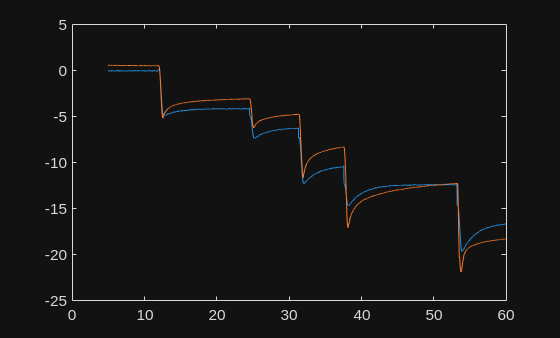


% Calculate the fitted force based on
%  the linear regression coefficients
fz_fitted = -A * projected_coeffs;
plot(t_adjusted_compression,fz_fitted);

hold on
plot(t_adjusted_compression,fz_compression);
hold off

% FOR DECOMPRESSION
% lets get the relaxation memory timer
relaxation_timer = [];
last_deformation_time = 0.0;
relaxation_steady_state = 2;

length = size(t_adjusted_decompression,1);

for i = 1:length
    if abs(z_v_filtered_decompression(i)) > 3e-4
        last_deformation_time = t_adjusted_decompression(i);
    end
    relaxation_timer(i) = t_adjusted_decompression(i) - last_deformation_time;
end

relaxation_component = [];
for i=1:length
    relaxation_component(i) = z(i)*exp(-relaxation_timer(i)/relaxation_steady_state);
end

%plot(t_adjusted_decompression,relaxation_component);


A = [z_decompression relaxation_component' z_v_filtered_decompression];
projected_coeffs = - inv(A' * A) * A' * fz_decompression;
k_decompression = projected_coeffs(1,1);
r_decompression = projected_coeffs(2,1);
zeta_decompression = projected_coeffs(3,1);

k_decompression,r_decompression,zeta_decompression

k_decompression = 1.7923e+03

r_decompression = -592.6010

zeta_decompression = 152.9966

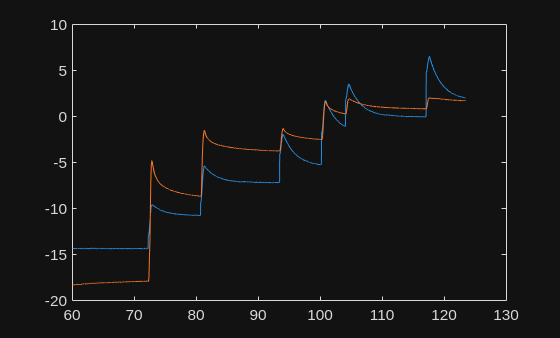


% Calculate the fitted force based on
%  the linear regression coefficients
fz_fitted = -A * projected_coeffs;
plot(t_adjusted_decompression,fz_fitted);

hold on
plot(t_adjusted_decompression,fz_decompression);
hold off